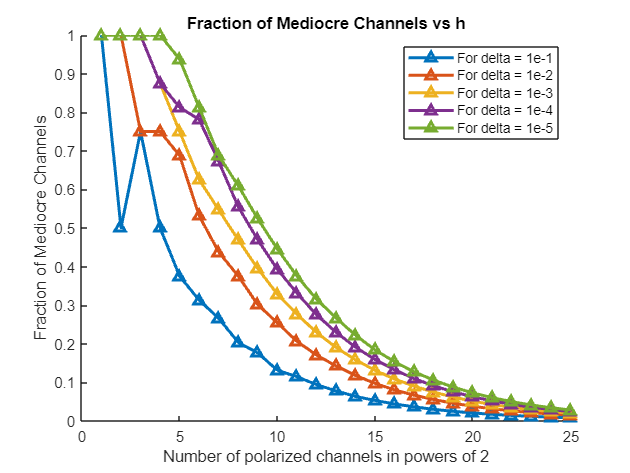

clearvars;
close all;
clc;

p = 0.5;
I = 1 - p;
hr = 1:1:25;
fraction = zeros(length(hr), 1);
deltax = [1e-1 1e-2 1e-3 1e-4 1e-5];
itr = 1;

for delta = deltax
    for h = hr
        nodes = 2^(h + 1) - 1;
        I_vec = zeros(nodes, 1);
        I_vec(1) = I;
        i = 1;
        while 2 * i + 1 <= nodes
            I_vec(2 * i) = I_vec(i)^2;
            I_vec(2 * i + 1) = 2 * I_vec(i) - I_vec(i)^2;
            i = i + 1;
        end
        polarized_channels = I_vec(i:end);
        Good_channels = polarized_channels(polarized_channels <= delta);
        Bad_channels = polarized_channels(polarized_channels >= (1 - delta));
        Mediocre_Channels = polarized_channels(polarized_channels >= delta & polarized_channels <= (1 - delta));
        fraction(h) = length(Mediocre_Channels) / 2^h;
    end
    hold on;
    plot(hr, fraction,'^-','LineWidth', 2);
end
xlabel('Number of polarized channels in powers of 2');
ylabel('Fraction of Mediocre Channels');
title('Fraction of Mediocre Channels vs h');
legend('For delta = 1e-1', 'For delta = 1e-2', 'For delta = 1e-3', 'For delta = 1e-4', 'For delta = 1e-5');